The infegrated test and figures are available under other script files. This is a minimalist example.

clc;
clear all;
addpath(genpath(pwd)); % add current directory to path (mcmcstat is included)
addpath(genpath('./../../one-step-experiements-v2'))
addpath('./simulator/');

addpath('/Users/rdey33/Downloads/MATLAB_DRIVE/mcmcstat/mcmcstat');

Showing for an example case of CBA18-3 on CBA 4

name = "CBA18-3_4";
load('./../data/one-step-data/'+name+'.mat');
[indi_i,indi_j]= name_matrix_function(name);
time_free_phages = time_free_phages/60;
load('parameters.mat','pars');

free_phages_mean = mean(free_phages,2);

data.ydata = free_phages_mean;
data.xdata = time_free_phages;

moi_mean = mean(moi);
S0 = 1e8;
V0 = S0*moi_mean;

% theta given by OSU lab
beta_osu = prior_values.burst_size;
r_osu = pars.r(indi_i);
phi_osu = pars.phi(indi_i,indi_j);
tau_osu = prior_values.latent_period/60  ;

theta_osu = [r_osu,phi_osu,tau_osu,beta_osu];


One example of inference

model.ssfun = @(theta,data)  error_function_NE_varies(theta,data,S0,V0);


params = {
% initial values for the model states
    {'r', r_osu, 0, 0.5, r_osu,0.05}
    {'phi', phi_osu,  1e-10, 1e-6, phi_osu, 1e-7 }
    {'tau', tau_osu,   0.25, 5, tau_osu, 1 }
    {'beta', beta_osu, 0, 700, beta_osu, 100}
    {'NE',70,5,200,70,50};
    };



options.nsimu = 1000;   %% do for 10000 times in real case
[results, chain, s2chain] = mcmcrun(model,data,params,options);

Sampling these parameters:
name   start [min,max] N(mu,s^2)
r: 0.190244 [0,0.5] N(0.190244,0.05^2)
phi: 1.83e-07 [1e-10,1e-06] N(1.83e-07,1e-07^2)
tau: 1 [0.25,5] N(1,1^2)
beta: 0.94 [0,700] N(0.94,100^2)
NE: 70 [5,200] N(70,50^2)


The results of the chain

chainstats(chain,results);

MCMC statistics, nsimu = 1000

                 mean         std      MC_err         tau      geweke
---------------------------------------------------------------------
         r    0.12267    0.038273   0.0065726      85.652     0.42668
       phi 8.9653e-08  3.0616e-08  5.3143e-09      97.338     0.31413
       tau    0.85609     0.35143    0.055392      47.697     0.89556
      beta     1.2613     0.51239     0.07371      42.775     0.45747
        NE     93.076      11.928      1.9601      58.838     0.76033
---------------------------------------------------------------------



Simulate the resultant time-series

burn = options.nsimu/2;
format short E;
theta_inferred = median(chain(burn:end,:))

theta_inferred =    1.0217e-01   7.8435e-08   9.3608e-01   1.1159e+00   9.8364e+01


NE = round(theta_inferred(5));
y0(1) = S0;
y0(2:NE+2) = 0;
y0(NE+3) = V0;



dilution_factor = 100;
[time,y_series_inferred] = one_step_simulate(time_free_phages,y0,median(chain(burn:end,:)),NE,dilution_factor);
[time2,y_series_osu] = one_step_simulate(time_free_phages,y0,theta_osu,NE,dilution_factor);

Resulting plots

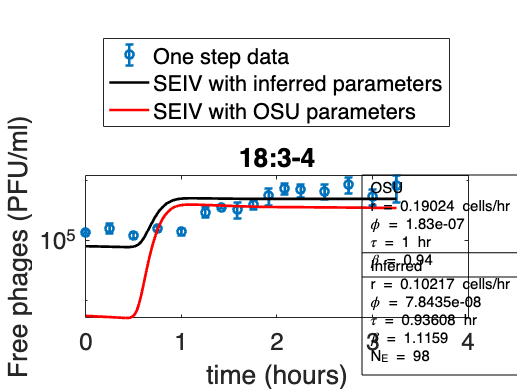

figure(2)
[~,something] = size(free_phages);
if something == 1
plot(time_free_phages,free_phages,'o','LineWidth', 2);
else
errorbar(time_free_phages,mean(free_phages,2),std(free_phages'),'LineWidth',2,'LineStyle','none','Marker','o');
end
xlabel('time (hours)','interpreter','none')
ylabel("Free phages (" +string(cell2mat(labels.units(1,3)))+")",'interpreter','none');
title(string(labels.phage)+'-'+string(labels.host));
hold on;
plot(time,y_series_inferred(end,:),'-k','LineWidth',2);hold on;
plot(time2,y_series_osu(end,:),'-r','LineWidth',2);
legend('One step data','SEIV with inferred parameters','SEIV with OSU parameters','Location','northoutside');
set(gca, 'YScale', 'log');
set(gca,'FontSize',18)
str = {['OSU'],['r = ',num2str(theta_osu(1)),' cells/hr'], ['\phi = ',num2str(theta_osu(2))], ['\tau = ',num2str(theta_osu(3)),' hr'], ['\beta = ',num2str(theta_osu(4))]};
annotation('textbox', [0.7, 0.45, 0.1, 0.1], 'String', str,'FontSize',11,'FitBoxToText','on');
str2 = {['Inferred'],['r = ',num2str(theta_inferred(1)),' cells/hr'], ['\phi = ',num2str(theta_inferred(2))], ['\tau = ',num2str(theta_inferred(3)),' hr'], ['\beta = ',num2str(theta_inferred(4))] ['N_E = ',num2str(round(theta_inferred(5)))]};
annotation('textbox', [0.7, 0.25, 0.1, 0.1], 'String', str2,'FontSize',11,'FitBoxToText','on');

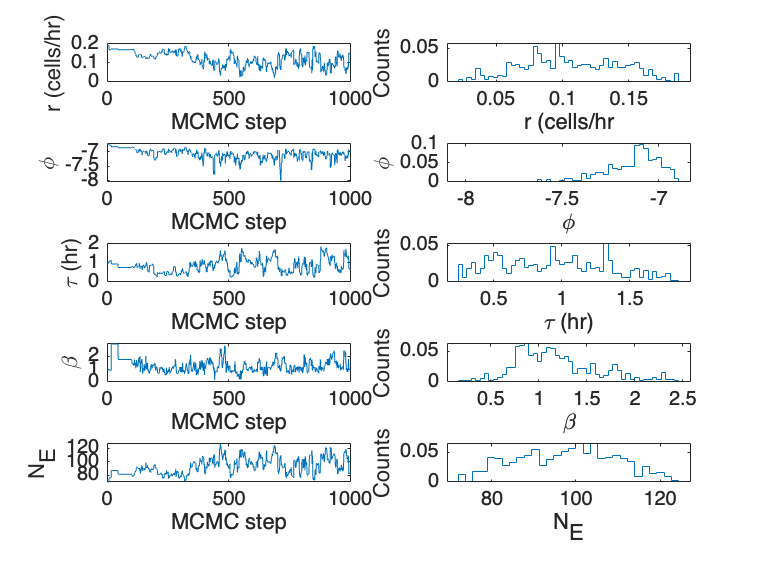



figure(3)
subplot(5,2,1)
plot(chain(:,1));xlabel('MCMC step');ylabel('r (cells/hr)');
subplot(5,2,2)
histogram(chain(burn:end,1),'Normalization','probability','DisplayStyle','stairs','NumBins',50); xlabel('r (cells/hr') ; ylabel('Counts');

subplot(5,2,3)
plot(log(chain(:,2))./log(10));xlabel('MCMC step');ylabel('\phi');
subplot(5,2,4)
histogram(log(chain(burn:end,2))./log(10),'Normalization','probability','DisplayStyle','stairs','NumBins',50); xlabel('\phi') ; ylabel('\phi');

subplot(5,2,5)
plot(chain(:,3));xlabel('MCMC step');ylabel('\tau (hr)');
subplot(5,2,6)
histogram(chain(burn:end,3),'Normalization','probability','DisplayStyle','stairs','NumBins',50); xlabel('\tau (hr)') ; ylabel('Counts');

subplot(5,2,7)
plot(chain(:,4));xlabel('MCMC step');ylabel('\beta');
subplot(5,2,8)
histogram(chain(burn:end,4),'Normalization','probability','DisplayStyle','stairs','NumBins',50); xlabel('\beta') ; ylabel('Counts');

subplot(5,2,9)
plot(chain(:,5));xlabel('MCMC step');ylabel('N_E');
subplot(5,2,10)
histogram(chain(burn:end,5),'Normalization','probability','DisplayStyle','stairs','NumBins',30); xlabel('N_E') ; ylabel('Counts');